# Lagrangian Mechanics of a Triple Pendulum System

Educational Live Script applying symbolic Lagrangian mechanics to a system of physical pendulums to simulate quasiperiodic and chaotic motion.

Author: D. Carlsmith

## Introduction

A double pendulum (one simple pendulum suspended from another) is well-known to exhibit quasiperiodic small-angle motions and chaotic large-angle motions. This educational Live script explores Lagrangian mechanics with a triple physical pendulum that exhibits chaotic motion. Variable parameters include a length scale, mass, and a moment of inertia per unit mass for each pendulum. Two visualization options are provided - equilateral triangles and, for fun, a hoop, cross-shape, and arrow, the components of symbols for Mars and Venus.

Symbolic methods are used to construct the Lagrangian and Euler equations of motion and to reduce the equations to a linear system for small-angle oscillations about equilibrium. The normal modes are found and illustrated. Numerical methods are employed to simulate and visualize large-angle motions and a suite of metrics is applied to classify these motions as periodic, quasi-periodic, or chaotic. 

This Live Script may interest students and instructors of physics and requires familiarity with intermediate-level mechanics. The symbolic Lagrangian methods may be applied to similar systems. 'Try this' suggestions, coding 'Challenges' , hyperlinks, and references are included for exploration. Additional educational Live Scripts by the author are available here..

## Background information

### Introduction to chaos

[Chaos theory](https://en.wikipedia.org/wiki/Chaos_theory) is used to describe the behavior of nonlinear systems exhibiting sensitivity to initial conditions. Such sensitivity can arise in a simple pendulum if it arrives stationary vertically upright at a point of unstable equilibrium - a small perturbation in angle or angular velocity will result in the angle increasing or decreasing. Chaos does not appear in systems described by linear differential equations. Such systems exhibit motions that are linearly dependent upon  initial conditions. For a single degree of freedom simple pendulum, the equation of motion for small angles is linear in the angle while for large angles it is nonlinear. Nonlinearity (smooth or discontinuous when arising from collisions) is associated with chaotic motion. 

A double pendulum (one simple pendulum hanging from another) can exhibit erratic/chaotic large-angle motions [1][2] like a forced nonlinear single pendulum. Chaotic motions are often characterized by a Lyapunov exponent $\lambda$ - two such solutions will have a separation $\delta {\bf X}$ in phase space that grows exponentially in time: $|\Delta {\bf x} (t)|\simeq^{\lambda t}|\Delta {\bf x} (0)|$ u. If the phase space is bounded, this growth will also be bonded. Other metrics for chaos exist.

This Live Script explores the motion of three physical pendulums like the three equilateral triangles shown below. The top triangle (1) is free to swing about one vertex and supports two similar additional triangles (2) and (3) from its lower vertices. We assume the bodies move in a common plane subject to gravity. We suppose the centers of mass of each physical pendulums is located the center of the triangle but the mass distribution and corresponding moment of inertia about the center of mass is arbitrary. Each object is assumed to always freely rotation about its pivot point free of collisions with other objects.

Let  the three triangles have sides $L_1$, $L_2$ and $L_3$, masses $m_1$, $m_2$ and $m_3$. Let $\theta_1$, $\theta_1$, and $\theta_3$ denote the angular deviation in the plane of the triangles from the vertical orientation. The kinetic energy of each triangle is the sum of the kinetic energy associated with the motion of its center of mass plus the kinetic energy of motion about its center of mass $K_i^{rot}= I_i(\dot\theta_i)^2/2$ where $I_i$ is the moment of inertia about the center-of-mass.

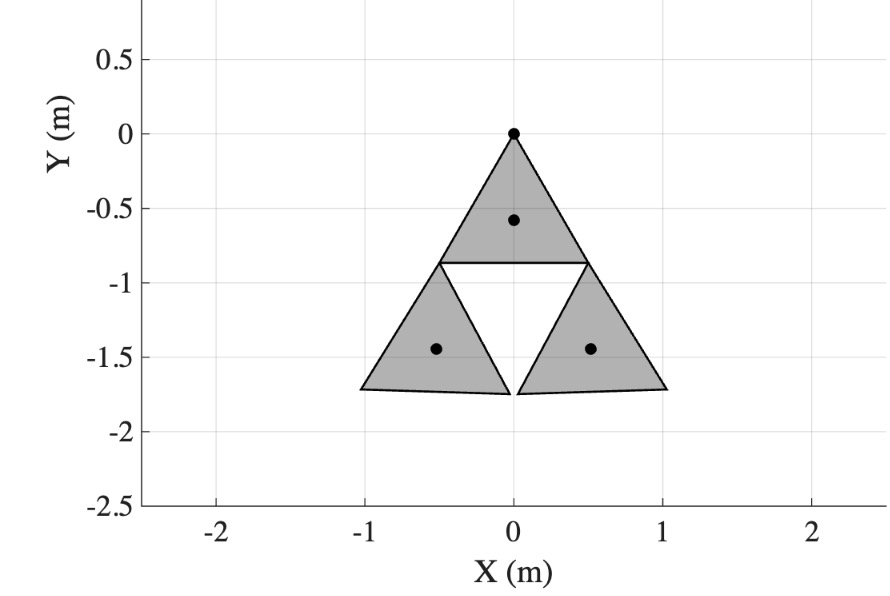

### Lagrangian mechanics

[Lagrangian mechanics](https://en.wikipedia.org/wiki/Lagrangian_mechanics) offers a convenient method to describe an energy-conserving mechanical system like ours. We first construct a Lagrangian function

 
$$L({\mathbf \theta},\dot{\mathbf \theta})=T({\mathbf \theta},\dot{\mathbf \theta})-V({\mathbf \theta})$$
 

of independent generalized coordinates ${\mathbf\theta}$ (in our case the angles of the pendulums) and their time derivatives $\dot{\mathbf\theta}$ all  regarded as independent variables. Here $T$ is the total kinetic energy and $V$ is the total potential energy. We will implicitly incorporate the geometric [holonomic constraints](https://en.wikipedia.org/wiki/Holonomic_constraints) relating ${\mathbf\theta}$ and $\dot {\mathbf\theta}$ through the geometry. The equations of motion are given by the Euler equations

${d\over dt}[{\partial L\over\partial\theta_i}] = {\partial L\over\partial{\dot\theta_i}$.

Since $L$ is a function of ${\mathbf\theta}$ and $\dot{\mathbf\theta}$, the time derivative on the left-hand-side of the Euler equations above contains terms proportional to generalize accelerations $\ddot{\mathbf\theta}$ with coefficients that depend on $\mathbf\theta}$ and $\dot{\mathbf\theta}$. These equations can be derived from Newton's laws with the forces and torques acting (respecting Newton's 3rd law) at the vertex points expressed in terms of the angles and their time derivatives. (See Ref[2] for an example of using Newton's Laws to derive the equations of motion for a simple double pendulum.) This system of equations can be written in a matrix form 


$${M}({\mathbf \theta},\dot{\mathbf \theta})\ddot{\mathbf\theta}={F}({\mathbf \theta},\dot{\mathbf \theta})$$


reminiscent of Newton's 2nd Law where ${M}$ is a $N\times N$ matrix with $N$ the number of generalized coordinates in the vector ${\mathbf\theta}$ and $F$ is a vector of generalized forces. It can be shown that $M=M(\mathbf \theta)$ is independent of the generalized velocities.

### Normal modes

As we will see, for small angular deviations from stable equilibrium, the equations of motion reduce to the linear form


$$M\ddot{\mathbf\theta}=-K{\mathbf\theta}$$


where the mass matrix $M$ and the stiffness matrix $K$ are both constant. In this case, solutions harmonic in time of the form $\mathbf\theta= {\mathbf\theta}_0e^{i\omega t}$ satisfy the equations

$[-\omega^2M+K]\mathbf \theta =0$.

This eigenvalue problem has solutions if the determinant $D\equiv |\omega^2M-K|$ vanishes. The equation $D=0$ is a polynomial equation of order $N$in $\omega^2$ with $N$ real roots called eigenfrequencies. Each frequency $\omega_i$ is associated with a constant eigenvector ${\mathbf \theta}_i$ and the general solution is a linear combination of eigensolutions ${\mathbf\theta}_i(t)= {\mathbf\theta}_{i}e^{i\omega_i t}$ called a normal modes. In this complex number notation, the coefficients in the general solution are complex and the real part of such a solution is to be taken and includes a phase angle. For $N=3$, there are three eigenvectors and the free parameters in the general solution are three amplitudes and three phases to be determined by specifying three angles and angular velocities at various times, usually taken to be some "initial" time $t=0$.

To the uninitiated, this succinct explication is a mouthful. Normal modes of a system of masses on a line connected by springs are analyzed in a Live Script in Ref[3]. Newton's Laws rather than Lagrangian mechanics are used to derive the equations of motion of a double pendulum in Ref[4]. Alibrary of examples using the Lagrangian approach is available at Ref[5].

### Properties of physical pendulums

Consider a uniform equilateral triangle with side length $L$, total mass $M$, and uniform density $\rho = M/A$ where the area is $A = \frac{\sqrt{3}}{4}L^2$ and $\rho = \frac{4M}{\sqrt{3}L^2}$. The height of the triangle is: $h = \frac{\sqrt{3}}{2}L$. Place the triangle with its base along the x-axis from $x = -L/2$ to $x = L/2$ at $y = 0$, with the apex at $(0, h)$. At height $y$ where $0 \leq y \leq h$, the width of the triangle is: $w(y) = L\left(1 - \frac{y}{h}\right)$. The moment of inertia about an axis perpendicular to the plane through the base is:


$$I_{base} = \int (x^2 + y^2) \rho \, dA = \rho \int_0^h \int_{-w(y)/2}^{w(y)/2} (x^2 + y^2) \, dx \, dy$$


Evaluate the $x^2$ integral and then the $y^2$ integral to find the moment of inertia about the base with $w(y) = L(1 - y/h)$:


$$I_{base} = \rho\left[\frac{L^3h}{48} + \frac{Lh^3}{12}\right] = \frac{\rho Lh(L^2 + 4h^2)}{48}$$


Substitute $h = \frac{\sqrt{3}}{2}L$, to find


$$I_{base} = \frac{\rho L^3h}{12} = \frac{4M}{\sqrt{3}L^2} \cdot \frac{L^3 \cdot \sqrt{3}L}{2 \cdot 12} = \frac{ML^2}{6}$$


Apply the [parallel axis theorem](https://en.wikipedia.org/wiki/Parallel_axis_theorem) to find the moment of inertia $I_{center}%$ about the center of the triangle. The centroid is at distance $d = h/3 = \frac{\sqrt{3}}{6}L$ from the base and 

$I_{base} = I_{center} + Md^2$$=I_{center} = \frac{ML^2}{6} - \frac{ML^2}{12} = \frac{ML^2}{12}$.

We can also find the momentum of inertia about a corner using the parallel axis theorem.


$$I_{vertex} = I_{center} + Md^2$$


where $d=L/{\sqrt{3}}$ is the distance from the centroid to the vertex. For an equilateral triangle, the centroid is located at the circumcenter. 

$I_{vertex} = \frac{ML^2}{12} + \frac{4ML^2}{12}=\frac{5ML^2}{12}$.

The frequency of small oscillations for a [physical pendulum](https://phys.libretexts.org/Bookshelves/Classical_Mechanics/Classical_Mechanics_(Dourmashkin)/24%3A_Physical_Pendulums/24.02%3A_Physical_Pendulum) is

  
$$f = \frac{1}{2\pi}\sqrt{\frac{mgd}{I}}$$


with $I$ the moment of inertia about the pivot point. Since $I\propto M$, the frequency depends only on the ratio of the inertial moment about the pivot point to the total mass. 

For a triangle pivoting at a corner:


$$I = \frac{5ML^2}{12}$$


and $d = \frac{L}{\sqrt{3}}$ so


$$f_{corner} = \frac{1}{2\pi}\sqrt{\frac{Mg \cdot \frac{L}{\sqrt{3}}}{\frac{5ML^2}{12}}}$$

$$= \frac{1}{2\pi}\sqrt{\frac{12MgL}{\sqrt{3} \cdot 5ML^2}} = \frac{1}{2\pi}\sqrt{\frac{12g}{5\sqrt{3}L}}$$

$$= \frac{1}{2\pi}\sqrt{\frac{4\sqrt{3}g}{5L}}$$


If we treat the triangle as a point mass ( $I_{center} = 0$), then the moment of inertia about the pivot at a corner is:

$I = Md^2$ where $d = \frac{L}{\sqrt{3}}$ and hence


$$I = M\left(\frac{L}{\sqrt{3}}\right)^2 = \frac{ML^2}{3}$$
 

and the frequency of small oscillations is


$$f_{point} = \frac{1}{2\pi}\sqrt{\frac{Mg \cdot \frac{L}{\sqrt{3}}}{\frac{ML^2}{3}}} = \frac{1}{2\pi}\sqrt{\frac{3MgL}{\sqrt{3}ML^2}} = \frac{1}{2\pi}\sqrt{\frac{3g}{\sqrt{3}L}}$$
 
$$= \frac{1}{2\pi}\sqrt{\frac{\sqrt{3}g}{L}}$$


For example, with $g = 9.81$ m/s², $L = 1$ m

$f_{corner} = \frac{1}{2\pi}\sqrt{\frac{4\sqrt{3} \times 9.81}{5 \times 1}}$ $= \frac{3.687}{6.283} = 0.587$ Hz

and

$f_{point} = \frac{1}{2\pi}\sqrt{\frac{\sqrt{3} \times 9.81}{1}}$ $= 0.656$ Hz

The simple pendulum approximation gives a frequency 12% higher than the physical pendulum because less rotational inertia means less resistance to angular acceleration. The expressions above may be useful in understanding the frequency spectra simulated by this script.

### Chaos Diagnostics Overview

The diagnostics code used in this script evaluates different mathematical signatures of deterministic chaos Ref[6-9].  Together, they provide a classification of the motion as periodic, quasi-periodic, or chaotic. 

1. The Gottwald–Melbourne 0–1 Test for Chaos 

This test transforms an observable $x_n$ into a cumulative walk in the complex plane:

$p(n) = \sum_{k=1}^{n} x_k \cos(c k)$, and $q(n) = \sum_{k=1}^{n} x_k \sin(c k)$,

where $c$ is a fixed irrational constant (typically $c=\pi/5$). The mean-square displacement is

 $M(n) = \frac{1}{N-n} \sum_{j=1}^{N-n} [(p_{j+n}-p_j)^2+(q_{j+n}-q_j)^2]$.

If $M(n)$ grows linearly with $n$, the motion is chaotic while if $M(n)$ saturates, the motion is regular. Define $K=\log(M)/\log(N)$.In the regular case (periodic or quasi-periodic dynamics) the trajectories for the system are typically bounded with $K\simeq0$, whereas in the chaotic case they  behave approximately like a two‐dimensional Brownian motion with $K\simeq 1$. This test sets a threshold on the quantity. It does not require phase-space reconstruction and is independent of the ergodic assumption. 

2. Correlation Dimension (Grassberger–Procaccia)

For an attractor (the manifold of points in phase space of a trajectory) reconstructed from state vectors $\mathbf{x}_i$, the correlation sum counts the fraction of pairs separated by less than $r$:

$C(r) = \frac{2}{N(N-1)} \sum_{i<j} H(r - \|\mathbf{x}_i - \mathbf{x}_j\|)$,

where $H$ is the Heaviside function. Over a scaling region, we expect  $C(r) \sim r^{D_2}$ and the slope of $\log C(r)$ versus $\log r$ gives the correlation dimension $D_2$. Periodic orbits have $D_2 \approx 1$, quasi-periodic motion yields $D_2 \approx 2$, and chaotic attractors show non-integer value $D_2 > 2$. 

 3. Spectral Analysis and Spectral Flatness

The power spectrum $P(f)$ of an observable reflects the frequency content of the motion.  The [spectral flatness](https://en.wikipedia.org/wiki/Spectral_flatness) (Wiener entropy) is defined as


$$\text{SF} = \frac{\exp[\frac{1}{N}\sum \ln(P(f))]}{\frac{1}{N}\sum P(f)}$$


It measures how "flat" or broadband the spectrum is. SF ≪ 0.1 indicates a single narrow spectral line (periodic motion), $0.1 < \text{SF} < 0.3$ suggests quasi-periodicity, $\text{SF} > 0.5$ indicates a broadband chaotic spectrum. 

4. Spectral Peak Count

Counting the number of significant peaks in the power spectrum $P(f)$ gives a simple measure of frequency complexity. Periodic signals show one or two dominant peaks, quasi-periodic signals have several peaks due to incommensurate frequencies, and chaotic signals exhibit many peaks or a continuous band.

Our three pendulum system will generally exhibit quasi-periodic small angle motions. The system is described by linear equations and a general solution is a linear combination of normal modes. The system has three degrees of freedom and hence three normal modes with eigenfrequencies which are generally incommensurate. Hence the general motion contains three distinct frequencies. Nonlinear terms in the equations of motion, e.g. terms proportional to $\theta_i^3$, will perturb the normal mode motions and result in a cascade of harmonic and combination terms, the simple harmonics dominating for small angles. As the amplitudes and nonlinearities grow, many frequencies will appear in the motion. 

5. Poincaré Section Spread

A Poincaré section samples the trajectory whenever a reference variable (say $\theta_1$) crosses a fixed plane ( $\theta_1 = 0$, $d\theta_1/dt > 0$). The coordinates $(\theta_2, \theta_3)$ at these crossings reveal the geometry of the motion: periodic motion yields a single point or small cluster, quasi-periodic motion forms closed loops, and chaotic motion produces a broad scatter. The standard deviation of these points quantifies this spread.

 6. Lyapunov Exponent Reliability and Weighted Voting

The Lyapunov exponent $\lambda$ measures the average exponential rate of divergence between nearby trajectories in phase space. For two infinitesimally close states with initial separation $d(0)$, the distance evolves approximately as

$d(t) \approx d(0) e^{\lambda t}$.

The exponent can be estimated by simulating the phase space trajectories of perturbed initial conditions. A positive $\lambda$ indicates sensitive dependence on initial conditions and chaotic dynamics, while $\lambda \le 0$ corresponds to periodic or quasi-periodic motion. In the diagnostic code, a one-dimensional finite-time estimate is used based on a single trajectory. The scalar observable $x_n$ (e.g., an angle) is divided into windows. Within each window:

1. For each point $x_i$, a nearest neighbor $x_j$ is found in value (excluding a small temporal window of $\pm 5$ samples to avoid trivial matches).

2. The initial separation is $d_0 = |x_i - x_j|$.

3. Both points are advanced one step to obtain $d_1 = |x_{i+1} - x_{j+1}|$.

4. The local divergence rate is computed as $g_i = \ln ({d_1}/{d_0})$.

5. The Lyapunov exponent for the window is then approximated by $\hat{\lambda} = \frac{1}{\Delta t} \langle g_i \rangle$ where $\Delta t$ is the sampling interval. The code rejects pairs that are too close or too far apart, limits large ratios, and averages across windows to obtain the mean, standard deviation, and coefficient of variation (CV) as a reliability measure. Because numerical estimates can fluctuate, the script computes $\lambda_{\max}$ in sliding windows and evaluates its coefficient of variation (CV).  If $\text{CV} < 0.5$, the estimate is considered reliable. 

The final classification of the motion as perodic, quasi-periodic, or chaotic combines all diagnostics with reliability-based weights. Reliable Lyapunov exponents receive higher weight; otherwise, other metrics dominate. Only when several independent indicators agree—positive and stable $\lambda_{\max}$, $K \approx 1$, large $D_2$, high spectral flatness, and scattered Poincaré points—does the diagnostic conclude that the motion is chaotic.

### Script operation notes

This script contains several sliders to set parameters. Control-click them to edit their behaviors. The script generates a variety of Live Script animations leveraging recently introduced automatic animation features. Each  animation may be saved as a video file using the button at the bottom right corner of the animation. These animations may not work in MATLAB Online due to bugs likely associated with system latencies.

The chaos diagnostics code is implemented as a separate Live Script using the same workspace, not as a function. This code is called by the main simulation code and may be run independently to reprocess simulation results.

## Initialize

clear all;
close all;
clc;
t0=tic;

### Try this: Set visualization mode.

Set the mode to 'triangles' for standard triangular shapes. Set the mode to 'special' for hoop, cross, and arrow shapes.

visualization_mode = 'special';
visualization_mode = 'triangles';
fprintf('Visualization mode: %s\n\n', visualization_mode);

Visualization mode: triangles



## Define symbolic variables

syms theta1 theta2 theta3 real
syms dtheta1 dtheta2 dtheta3 real
syms l1 l2 l3 m1 m2 m3 g t real

## Define triangle 1 geometry in Cartesian coordinates

Set coordinates  for vertices of triangle 1 in terms of the length $l_1$ of a side and the angle $\theta_1$.

x1_v1 = 0;
y1_v1 = 0;
x1_v2 = l1 * sin(theta1 - pi/6);
y1_v2 = -l1 * cos(theta1 - pi/6);
x1_v3 = l1 * sin(theta1 + pi/6);
y1_v3 = -l1 * cos(theta1 + pi/6);

Define the corresponding location of the center of mass of triangle 1.

x1_cm = (x1_v1 + x1_v2 + x1_v3) / 3;
y1_cm = (y1_v1 + y1_v2 + y1_v3) / 3;

x1_cm = simplify(x1_cm)

$$x1\_cm = \frac{\sqrt{3}\,l_{1}\,\sin\left(\theta_{1}\right)}{3}$$

y1_cm = simplify(y1_cm)

$$y1\_cm = -\frac{\sqrt{3}\,l_{1}\,\cos\left(\theta_{1}\right)}{3}$$

## Define triangle 2 geometry in Cartesian coordinates

Use cartesian coordinates.Triangle 2 Geometry  is coupled to Triangle 1 geometry through the pivot position.

x2_pivot = x1_v2

$$x2\_pivot = l_{1}\,\sin\left(\theta_{1}-\frac{\pi }{6}\right)$$

y2_pivot = y1_v2

$$y2\_pivot = -l_{1}\,\cos\left(\theta_{1}-\frac{\pi }{6}\right)$$

x2_v1 = x2_pivot;
y2_v1 = y2_pivot;
x2_v2 = x2_pivot + l2 * sin(theta2 - pi/6);
y2_v2 = y2_pivot - l2 * cos(theta2 - pi/6);
x2_v3 = x2_pivot + l2 * sin(theta2 + pi/6);
y2_v3 = y2_pivot - l2 * cos(theta2 + pi/6);

x2_cm = (x2_v1 + x2_v2 + x2_v3) / 3;
y2_cm = (y2_v1 + y2_v2 + y2_v3) / 3;

x2_cm = simplify(x2_cm)

$$x2\_cm = \frac{\sqrt{3}\,l_{1}\,\sin\left(\theta_{1}\right)}{2}-\frac{l_{1}\,\cos\left(\theta_{1}\right)}{2}+\frac{\sqrt{3}\,l_{2}\,\sin\left(\theta_{2}\right)}{3}$$

y2_cm = simplify(y2_cm)

$$y2\_cm = -\frac{l_{1}\,\sin\left(\theta_{1}\right)}{2}-\frac{\sqrt{3}\,l_{1}\,\cos\left(\theta_{1}\right)}{2}-\frac{\sqrt{3}\,l_{2}\,\cos\left(\theta_{2}\right)}{3}$$

The location of the center of mass of triangle 2 depends on $\theta_1$ and $\theta_2$.

## Define triangle 3 geometry in Cartesian coordinates

Follow steps similar to those for Triangle 2.

x3_pivot = x1_v3;
y3_pivot = y1_v3;

x3_v1 = x3_pivot;
y3_v1 = y3_pivot;
x3_v2 = x3_pivot + l3 * sin(theta3 - pi/6);
y3_v2 = y3_pivot - l3 * cos(theta3 - pi/6);
x3_v3 = x3_pivot + l3 * sin(theta3 + pi/6);
y3_v3 = y3_pivot - l3 * cos(theta3 + pi/6);

x3_cm = (x3_v1 + x3_v2 + x3_v3) / 3;
y3_cm = (y3_v1 + y3_v2 + y3_v3) / 3;

x3_cm = simplify(x3_cm)

$$x3\_cm = \frac{l_{1}\,\cos\left(\theta_{1}\right)}{2}+\frac{\sqrt{3}\,l_{1}\,\sin\left(\theta_{1}\right)}{2}+\frac{\sqrt{3}\,l_{3}\,\sin\left(\theta_{3}\right)}{3}$$

y3_cm = simplify(y3_cm)

$$y3\_cm = \frac{l_{1}\,\sin\left(\theta_{1}\right)}{2}-\frac{\sqrt{3}\,l_{1}\,\cos\left(\theta_{1}\right)}{2}-\frac{\sqrt{3}\,l_{3}\,\cos\left(\theta_{3}\right)}{3}$$

## Define velocities for the centers of mass of all three triangles in Cartesian coordinates

vx1_cm = diff(x1_cm, theta1) * dtheta1;
vy1_cm = diff(y1_cm, theta1) * dtheta1;

vx2_cm = diff(x2_cm, theta1) * dtheta1 + diff(x2_cm, theta2) * dtheta2;
vy2_cm = diff(y2_cm, theta1) * dtheta1 + diff(y2_cm, theta2) * dtheta2;

vx2_cm = simplify(expand(vx2_cm))

$$vx2\_cm = \frac{{\mathrm{dtheta}}_{1}\,l_{1}\,\sin\left(\theta_{1}\right)}{2}+\frac{\sqrt{3}\,{\mathrm{dtheta}}_{1}\,l_{1}\,\cos\left(\theta_{1}\right)}{2}+\frac{\sqrt{3}\,{\mathrm{dtheta}}_{2}\,l_{2}\,\cos\left(\theta_{2}\right)}{3}$$

vy2_cm = simplify(expand(vy2_cm))

$$vy2\_cm = \frac{\sqrt{3}\,{\mathrm{dtheta}}_{1}\,l_{1}\,\sin\left(\theta_{1}\right)}{2}-\frac{{\mathrm{dtheta}}_{1}\,l_{1}\,\cos\left(\theta_{1}\right)}{2}+\frac{\sqrt{3}\,{\mathrm{dtheta}}_{2}\,l_{2}\,\sin\left(\theta_{2}\right)}{3}$$

vx3_cm = diff(x3_cm, theta1) * dtheta1 + diff(x3_cm, theta3) * dtheta3;
vy3_cm = diff(y3_cm, theta1) * dtheta1 + diff(y3_cm, theta3) * dtheta3;

vx3_cm = simplify(expand(vx3_cm));
vy3_cm = simplify(expand(vy3_cm));

## Construct the total kinetic energy associated with center of mass motion using the velocity vectors

Define kinetic energies of the motions of the centers of mass.

T_trans1 = (1/2) * m1 * (vx1_cm^2 + vy1_cm^2);
T_trans2 = (1/2) * m2 * (vx2_cm^2 + vy2_cm^2);
T_trans3 = (1/2) * m3 * (vx3_cm^2 + vy3_cm^2);

## Define moments of inertia about the centers of mass

### Try this: Set the moments of inertia about the center of mass for each triangle.

Choose from the following or add a custom set of inertia moments.

1) A triangle mass distribution concentrated at the center of mass, $I=0$. 

2) For point masses at the vertices only, $I=2ML^2$.

3) The distance from the center to vertex of an equilateral triangle of side $L$ is $L/\sqrt{3}$. The moment of inertia about the center of mass of a uniform density triangle is $I= ML^2/12$ and about a corner is  $I = 5ML^2/12$. 

inertia_type_default=1;
inertia_type=1;
switch inertia_type
    case 1
    I1=0;
    I2=0;
    I3=0;
    case 2
    I1 = 2* m1 * l1^2 / 12;
    I2 = 2* m2 * l2^2 / 12;
    I3 = 2* m3 * l3^2 / 12;
    case 3
    I1 = m1 * l1^2 / 12;
    I2 = m2 * l2^2 / 12;
    I3 = m3 * l3^2 / 12;
    otherwise
        display('Unsupported inertia type. Quitting.')
        return
end        

## Define triangle kinetic energies 

Define the kinetic energy of rotation about the center of mass for each object: $K=(1/2)I(\dot \theta )^2$.

T_rot1 = (1/2) * I1 * dtheta1^2;
T_rot2 = (1/2) * I2 * dtheta2^2;
T_rot3 = (1/2) * I3 * dtheta3^2;

Define the total rotational kinetic energy.

T = T_trans1 + T_trans2 + T_trans3 + T_rot1 + T_rot2 + T_rot3;
T = collect(simplify(expand(T)),dtheta1)

$$T = \left(\frac{{l_{1}}^{2}\,m_{1}}{6}+\frac{{l_{1}}^{2}\,m_{2}}{2}+\frac{{l_{1}}^{2}\,m_{3}}{2}\right)\,{{\mathrm{dtheta}}_{1}}^{2}+\left(\frac{{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{1}-\theta_{2}\right)}{2}+\frac{{\mathrm{dtheta}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(\theta_{1}-\theta_{3}\right)}{2}+\frac{\sqrt{3}\,{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)}{6}-\frac{\sqrt{3}\,{\mathrm{dtheta}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(\theta_{1}-\theta_{3}\right)}{6}\right)\,{\mathrm{dtheta}}_{1}+\frac{m_{2}\,{{\mathrm{dtheta}}_{2}}^{2}\,{l_{2}}^{2}}{6}+\frac{m_{3}\,{{\mathrm{dtheta}}_{3}}^{2}\,{l_{3}}^{2}}{6}$$

Display couplings.

coupling_12 = diff(diff(T, dtheta1), dtheta2)

$$coupling\_12 = \frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{1}-\theta_{2}\right)}{2}+\frac{\sqrt{3}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)}{6}$$

coupling_13 = diff(diff(T, dtheta1), dtheta3)

$$coupling\_13 = \frac{l_{1}\,l_{3}\,m_{3}\,\cos\left(\theta_{1}-\theta_{3}\right)}{2}-\frac{\sqrt{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(\theta_{1}-\theta_{3}\right)}{6}$$

coupling_23 = diff(diff(T, dtheta2), dtheta3)

$$coupling\_23 = 0$$

## Construct the total potential energy

V = m1 * g * y1_cm + m2 * g * y2_cm + m3 * g * y3_cm;

## Construct the system Lagrangian

L = T - V;
L = simplify(L)

$$L = \begin{array}{l} {{\mathrm{dtheta}}_{1}}^{2}\,\left(\frac{{l_{1}}^{2}\,m_{1}}{6}+\frac{{l_{1}}^{2}\,m_{2}}{2}+\frac{{l_{1}}^{2}\,m_{3}}{2}\right)+{\mathrm{dtheta}}_{1}\,\left(\frac{{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{1}-\theta_{2}\right)}{2}+\frac{{\mathrm{dtheta}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(\theta_{1}-\theta_{3}\right)}{2}+\frac{\sqrt{3}\,{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)}{6}-\frac{\sqrt{3}\,{\mathrm{dtheta}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(\theta_{1}-\theta_{3}\right)}{6}\right)+g\,m_{2}\,\left(\sigma_{2}+\sigma_{1}+\frac{\sqrt{3}\,l_{2}\,\cos\left(\theta_{2}\right)}{3}\right)+g\,m_{3}\,\left(\sigma_{1}-\sigma_{2}+\frac{\sqrt{3}\,l_{3}\,\cos\left(\theta_{3}\right)}{3}\right)+\frac{{{\mathrm{dtheta}}_{2}}^{2}\,{l_{2}}^{2}\,m_{2}}{6}+\frac{{{\mathrm{dtheta}}_{3}}^{2}\,{l_{3}}^{2}\,m_{3}}{6}+\frac{\sqrt{3}\,g\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)}{3}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,l_{1}\,\cos\left(\theta_{1}\right)}{2}\\ \sigma_{2}=\frac{l_{1}\,\sin\left(\theta_{1}\right)}{2} \end{array}$$

## Derive the Euler equations of motion

syms ddtheta1 ddtheta2 ddtheta3 real

Start with the Euler equation for the 1st  angular variable.

Construct ${\partial L\over \partial \theta_1}$.

dL_dtheta1 = diff(L, theta1);

Construct ${\partial L\over \partial \dot\theta_1}$.

dL_ddtheta1 = diff(L, dtheta1);

Using the chain rule, construct ${d\over dt}{\partial L\over \partial \dot\theta_1}$ $=\sum_i {\partial \over\partial\theta_i}[{\partial L\over \partial \theta_1}]\dot\theta_i+\sum_i {\partial \over\partial\dot \theta_i}[{\partial L\over \partial\dot \theta_1}]\ddot\theta_i}$.

dt_dL_ddtheta1 = diff(dL_ddtheta1, theta1) * dtheta1 + ...
                 diff(dL_ddtheta1, theta2) * dtheta2 + ...
                 diff(dL_ddtheta1, theta3) * dtheta3 + ...
                 diff(dL_ddtheta1, dtheta1) * ddtheta1 + ...
                 diff(dL_ddtheta1, dtheta2) * ddtheta2 + ...
                 diff(dL_ddtheta1, dtheta3) * ddtheta3;

Euler equation 1: ${d\over dt}{\partial L\over \partial \dot\theta_1}-{\partial L\over \partial \theta_1}=0$

EOM1 = dt_dL_ddtheta1 - dL_dtheta1;
EOM1 = simplify(EOM1);

Repeat for the 2nd and 3rd Euler equations.

dL_dtheta2 = diff(L, theta2);
dL_ddtheta2 = diff(L, dtheta2);

dt_dL_ddtheta2 = diff(dL_ddtheta2, theta1) * dtheta1 + ...
                 diff(dL_ddtheta2, theta2) * dtheta2 + ...
                 diff(dL_ddtheta2, theta3) * dtheta3 + ...
                 diff(dL_ddtheta2, dtheta1) * ddtheta1 + ...
                 diff(dL_ddtheta2, dtheta2) * ddtheta2 + ...
                 diff(dL_ddtheta2, dtheta3) * ddtheta3;

EOM2 = dt_dL_ddtheta2 - dL_dtheta2;
EOM2 = simplify(EOM2);

dL_dtheta3 = diff(L, theta3);
dL_ddtheta3 = diff(L, dtheta3);

dt_dL_ddtheta3 = diff(dL_ddtheta3, theta1) * dtheta1 + ...
                 diff(dL_ddtheta3, theta2) * dtheta2 + ...
                 diff(dL_ddtheta3, theta3) * dtheta3 + ...
                 diff(dL_ddtheta3, dtheta1) * ddtheta1 + ...
                 diff(dL_ddtheta3, dtheta2) * ddtheta2 + ...
                 diff(dL_ddtheta3, dtheta3) * ddtheta3;

EOM3 = dt_dL_ddtheta3 - dL_dtheta3;
EOM3 = simplify(EOM3);

## Display the Euler equations

disp(EOM1 == 0);

$$\begin{array}{l} {\mathrm{dtheta}}_{2}\,\left(\frac{{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)}{2}-\frac{\sqrt{3}\,{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{1}-\theta_{2}\right)}{6}\right)+{\mathrm{dtheta}}_{3}\,\left(\frac{{\mathrm{dtheta}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(\theta_{1}-\theta_{3}\right)}{2}+\frac{\sqrt{3}\,{\mathrm{dtheta}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(\theta_{1}-\theta_{3}\right)}{6}\right)+{\mathrm{ddtheta}}_{1}\,\left(\frac{{l_{1}}^{2}\,m_{1}}{3}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}\right)+{\mathrm{ddtheta}}_{2}\,\left(\frac{l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{1}-\theta_{2}\right)}{2}+\frac{\sqrt{3}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)}{6}\right)+{\mathrm{ddtheta}}_{3}\,\left(\frac{l_{1}\,l_{3}\,m_{3}\,\cos\left(\theta_{1}-\theta_{3}\right)}{2}-\frac{\sqrt{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(\theta_{1}-\theta_{3}\right)}{6}\right)-g\,m_{2}\,\left(\sigma_{2}-\sigma_{1}\right)+g\,m_{3}\,\left(\sigma_{2}+\sigma_{1}\right)+\frac{\sqrt{3}\,g\,l_{1}\,m_{1}\,\sin\left(\theta_{1}\right)}{3}=0\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,l_{1}\,\sin\left(\theta_{1}\right)}{2}\\ \sigma_{2}=\frac{l_{1}\,\cos\left(\theta_{1}\right)}{2} \end{array}$$

disp(EOM2 == 0);

$$\frac{l_{2}\,m_{2}\,\left(2\,{\mathrm{ddtheta}}_{2}\,l_{2}+2\,\sqrt{3}\,g\,\sin\left(\theta_{2}\right)+3\,{\mathrm{ddtheta}}_{1}\,l_{1}\,\cos\left(\theta_{1}-\theta_{2}\right)-3\,{{\mathrm{dtheta}}_{1}}^{2}\,l_{1}\,\sin\left(\theta_{1}-\theta_{2}\right)+\sqrt{3}\,{\mathrm{ddtheta}}_{1}\,l_{1}\,\sin\left(\theta_{1}-\theta_{2}\right)+\sqrt{3}\,{{\mathrm{dtheta}}_{1}}^{2}\,l_{1}\,\cos\left(\theta_{1}-\theta_{2}\right)\right)}{6}=0$$

disp(EOM3 == 0);

$$\frac{l_{3}\,m_{3}\,\left(2\,{\mathrm{ddtheta}}_{3}\,l_{3}+2\,\sqrt{3}\,g\,\sin\left(\theta_{3}\right)+3\,{\mathrm{ddtheta}}_{1}\,l_{1}\,\cos\left(\theta_{1}-\theta_{3}\right)-3\,{{\mathrm{dtheta}}_{1}}^{2}\,l_{1}\,\sin\left(\theta_{1}-\theta_{3}\right)-\sqrt{3}\,{\mathrm{ddtheta}}_{1}\,l_{1}\,\sin\left(\theta_{1}-\theta_{3}\right)-\sqrt{3}\,{{\mathrm{dtheta}}_{1}}^{2}\,l_{1}\,\cos\left(\theta_{1}-\theta_{3}\right)\right)}{6}=0$$

## Extract the mass matrix

M11 = diff(EOM1, ddtheta1);
M12 = diff(EOM1, ddtheta2);
M13 = diff(EOM1, ddtheta3);

M21 = diff(EOM2, ddtheta1);
M22 = diff(EOM2, ddtheta2);
M23 = diff(EOM2, ddtheta3);

M31 = diff(EOM3, ddtheta1);
M32 = diff(EOM3, ddtheta2);
M33 = diff(EOM3, ddtheta3);

M_matrix = [M11, M12, M13; M21, M22, M23; M31, M32, M33];
M_matrix = simplify(M_matrix)

$$M\_matrix = \begin{array}{l} \left(\begin{array}{ccc} \frac{{l_{1}}^{2}\,\left(m_{1}+3\,m_{2}+3\,m_{3}\right)}{3} & \sigma_{2} & \sigma_{1}\\ \sigma_{2} & \frac{{l_{2}}^{2}\,m_{2}}{3} & 0\\ \sigma_{1} & 0 & \frac{{l_{3}}^{2}\,m_{3}}{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(\theta_{1}-\theta_{3}+\frac{\pi }{6}\right)}{3}\\ \sigma_{2}=\frac{\sqrt{3}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}-\theta_{1}+\frac{\pi }{6}\right)}{3} \end{array}$$

## Construct the force vectors.

F1 = -subs(EOM1, [ddtheta1, ddtheta2, ddtheta3], [0, 0, 0]);
F2 = -subs(EOM2, [ddtheta1, ddtheta2, ddtheta3], [0, 0, 0]);
F3 = -subs(EOM3, [ddtheta1, ddtheta2, ddtheta3], [0, 0, 0]);

F_vector = [F1; F2; F3];
F_vector = simplify(F_vector)

$$F\_vector = \begin{array}{l} \left(\begin{array}{c} g\,m_{2}\,\left(\sigma_{2}-\sigma_{1}\right)-{\mathrm{dtheta}}_{3}\,\left(\frac{{\mathrm{dtheta}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\sin\left(\theta_{1}-\theta_{3}\right)}{2}+\frac{\sqrt{3}\,{\mathrm{dtheta}}_{3}\,l_{1}\,l_{3}\,m_{3}\,\cos\left(\theta_{1}-\theta_{3}\right)}{6}\right)-{\mathrm{dtheta}}_{2}\,\left(\frac{{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{1}-\theta_{2}\right)}{2}-\frac{\sqrt{3}\,{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{1}-\theta_{2}\right)}{6}\right)-g\,m_{3}\,\left(\sigma_{2}+\sigma_{1}\right)-\frac{\sqrt{3}\,g\,l_{1}\,m_{1}\,\sin\left(\theta_{1}\right)}{3}\\ -\frac{l_{2}\,m_{2}\,\left(2\,\sqrt{3}\,g\,\sin\left(\theta_{2}\right)-3\,{{\mathrm{dtheta}}_{1}}^{2}\,l_{1}\,\sin\left(\theta_{1}-\theta_{2}\right)+\sqrt{3}\,{{\mathrm{dtheta}}_{1}}^{2}\,l_{1}\,\cos\left(\theta_{1}-\theta_{2}\right)\right)}{6}\\ \frac{l_{3}\,m_{3}\,\left(3\,{{\mathrm{dtheta}}_{1}}^{2}\,l_{1}\,\sin\left(\theta_{1}-\theta_{3}\right)-2\,\sqrt{3}\,g\,\sin\left(\theta_{3}\right)+\sqrt{3}\,{{\mathrm{dtheta}}_{1}}^{2}\,l_{1}\,\cos\left(\theta_{1}-\theta_{3}\right)\right)}{6} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,l_{1}\,\sin\left(\theta_{1}\right)}{2}\\ \sigma_{2}=\frac{l_{1}\,\cos\left(\theta_{1}\right)}{2} \end{array}$$

## Set numerical values for the system parameters

### Try this: Set the lengths of the sides of the triangles.

Set $l_1=1$as a standard. Change the other two lengths using a scaling factor as desired below.

l1_val = 1.0;
l2_val = l1_val / 1;
l3_val = l1_val / 2;

### Try this: Set the masses of the triangles.

The masses have no absolute significance as the motions depend only upon the ratio of the moment of inertia about the center of mass to the the mass which is mass independent. However, the mass ratios will determine the equilibrium configuration.

m1_val = 1.0;
m2_val = m1_val / 1;
m3_val = m1_val / 2;

Set $m_3=m_2$ so that these weights balance and the stable equilibrium has all triangles hanging symmetrically from their pivots points with zero angles as defined below with triangles 2 and 3 at equal heights.

Note: Comment this out for different masses as desired.

%m3_val = m2_val;

Set the acceleration of gravity. 

g_val = 9.81;

Display values.

fprintf('l1 = %.2f m, l2 = %.2f m, l3 = %.2f m\n', l1_val, l2_val, l3_val);

l1 = 1.00 m, l2 = 1.00 m, l3 = 0.50 m


fprintf('m1 = %.2f kg, m2 = %.2f kg, m3 = %.2f kg\n', m1_val, m2_val, m3_val);

m1 = 1.00 kg, m2 = 1.00 kg, m3 = 0.50 kg


fprintf('g = %.2f m/s^2\n\n', g_val);

g = 9.81 m/s^2



## Convert symbolic functions to numerical functions using numerical values for the parameters

M_matrix_num = subs(M_matrix, [l1, l2, l3, m1, m2, m3, g], ...
                    [l1_val, l2_val, l3_val, m1_val, m2_val, m3_val, g_val]);
F_vector_num = subs(F_vector, [l1, l2, l3, m1, m2, m3, g], ...
                    [l1_val, l2_val, l3_val, m1_val, m2_val, m3_val, g_val]);

M_func = matlabFunction(M_matrix_num, 'Vars', [theta1, theta2, theta3, dtheta1, dtheta2, dtheta3]);
F_func = matlabFunction(F_vector_num, 'Vars', [theta1, theta2, theta3, dtheta1, dtheta2, dtheta3]);

T_num = subs(T, [l1, l2, l3, m1, m2, m3], [l1_val, l2_val, l3_val, m1_val, m2_val, m3_val]);
V_num = subs(V, [l1, l2, l3, m1, m2, m3, g], [l1_val, l2_val, l3_val, m1_val, m2_val, m3_val, g_val]);
E_func = matlabFunction(T_num + V_num, 'Vars', [theta1, theta2, theta3, dtheta1, dtheta2, dtheta3]);

## Set initial conditions

For simplicity, assume all pendulums start at rest at t=0 with some initial angles.

dtheta1_0 = 0;
dtheta2_0 = 0;
dtheta3_0 = 0;

### Try this: Set initial angles in radians.

Choose from the cases below or customize.

initialangle_default=1;
initialangle=-1;
switch initialangle

### Large-angle initial conditions.

Case -1 with $l_1=l_2=l_3=1$ and $I_1=I_2=I_3=0$, $m_1=m_2=m_3$ and $\theta_1=0$ with $\theta_2=-\theta_3$ results in equal and opposite swings of triangles 2 and 3 with triangle 1 stationary, but in chaos after about 50 s due to numerical precision.

    case -1
    theta1_0 = 0 * pi / 180;
    theta2_0 = -120 * pi/180;
    theta3_0 = +120 * pi / 180;

Case 0 for equal lengths and masses has triangle 1 initially inverted with maximum potential energy.

    case 0
    theta1_0 = 180 * pi / 180;
    theta2_0 = 0 * pi/180;
    theta3_0 = 20 * pi / 180;

    case 1
    theta1_0 = 150 * pi / 180;
    theta2_0 = 140 * pi/180;
    theta3_0 = 180 * pi / 180;

### Small-angle initial conditions

Case 2 is a generic set of fairly small angles.

    case 2
    theta1_0 = 10 * pi / 180;
    theta2_0 = 5 *pi/180;
    theta3_0 = 7.5 * pi / 180;

Case 3 is a symmetric displacement of triangles 2 and 3 with triangle 1 in equilibrium forever to machine precision.

    case 3
    theta1_0 = 0 * pi / 180;
    theta2_0 = 5 *pi/180;
    theta3_0 = -5 * pi / 180;

Cases 4 and 5 start with all triangles displaced in the same direction. As that angle is increased, the nonlinearity and the power in harmonic frequencies increases.

    case 4
    theta1_0 = 5 *pi/180;
    theta2_0 = 5 *pi/180;
    theta3_0 = 5 *pi/180;

    case 5
    theta1_0 = 1 *pi/180;
    theta2_0 = 1 *pi/180;
    theta3_0 = 1 *pi/180;
    otherwise
        disp('Bad initial angle')
end

Bundle initial conditions into a vector.

y0 = [theta1_0; theta2_0; theta3_0; dtheta1_0; dtheta2_0; dtheta3_0];
fprintf('theta1(0) = %.2f°,  theta2(0) = %.2f°,  theta3(0) = %.2f°\n', ...
        theta1_0 * 180 / pi, theta2_0 * 180 / pi, theta3_0 * 180 / pi);

theta1(0) = 0.00°,  theta2(0) = -120.00°,  theta3(0) = 120.00°


## Set the simulation time

Compute the simulation time as a multiple of the longest pendulum period, assuming vanishing inertial moments.

T1_period = 2 * pi * sqrt((l1_val/sqrt(3)) / g_val);
T2_period = 2 * pi * sqrt((l2_val/sqrt(3)) / g_val);
T3_period = 2 * pi * sqrt((l3_val/sqrt(3)) / g_val);
max_period = max([T1_period, T2_period, T3_period]);

### Try this: Set the number of periods to simulate.

About 50 periods should be sufficient to resolve frequencies of order 1 Hz with percent-level accuracy.

num_periods_default=50;
num_periods=50;
t_final = 50 * max_period;
fprintf('Simulating for: %.2f s (10 periods)\n\n', t_final);

Simulating for: 76.21 s (10 periods)



toc(t0)

Elapsed time is 1.835006 seconds.


## Linearization, eigenanalysis, and normal mode determination.

Linearize about theta = [0 0 0] keeping quadratic terms in the Lagrangian.

Symbolic vectors

q  = [theta1; theta2; theta3];
dq = [dtheta1; dtheta2; dtheta3];

Mass (inertial) matrix from quadratic form of T.

M_lin_sym = jacobian(jacobian(T, dq), dq);
M_lin_sym = subs(M_lin_sym, [theta1, theta2, theta3], [0, 0, 0]);
M_lin_sym = simplify(M_lin_sym);

Stiffness matrix from potential V: M*qdd + K*q = 0.

K_lin_sym = hessian(V, q);
K_lin_sym = subs(K_lin_sym, [theta1, theta2, theta3], [0, 0, 0]);
K_lin_sym = simplify(K_lin_sym);

Substitute numerical parameters into the mass and stiffness matrices.

M_lin_num = subs(M_lin_sym, [l1, l2, l3, m1, m2, m3, g], ...
                           [l1_val, l2_val, l3_val, m1_val, m2_val, m3_val, g_val]);
K_lin_num = subs(K_lin_sym, [l1, l2, l3, m1, m2, m3, g], ...
                           [l1_val, l2_val, l3_val, m1_val, m2_val, m3_val, g_val]);

M_lin = double(M_lin_num)

M_lin =     1.8333    0.5000    0.1250
    0.5000    0.3333         0
    0.1250         0    0.0417


K_lin = double(K_lin_num)

K_lin =    18.4074         0         0
         0    5.6638         0
         0         0    1.4160


Find the eigenvalues of the eigenproblem: K * phi = (omega^2) * M * phi,

[Phi_raw, D_raw] = eig(K_lin, M_lin);

Drop any imaginary parts that might arise from numerical error.

omega2 = real(diag(D_raw));

Keep nonnegative eigenvalues and sort them by frequency.

omega2(omega2 < 0) = 0;
omega = sqrt(omega2);
[omega, idx_sort] = sort(omega, 'ascend');
Phi_raw = Phi_raw(:, idx_sort);

Mass-normalize the eigenvectors: phi_i^T M phi_i = 1.

Phi = zeros(size(Phi_raw));
for i = 1:size(Phi_raw,2)
    v = Phi_raw(:,i);
    mnorm = sqrt(real(v.' * M_lin * v));
    if mnorm > 0
        v = v / mnorm;
    end    

Scale the eigenvectors so the maximal component magnitude is 1 for visual convenience.

    vmax = max(abs(v));
    if vmax > 0
        v = v / vmax;
    end
    Phi(:,i) = real(v);
end

Display the  small-angle natural frequencies.

f_hz = omega/(2*pi);
fprintf('Natural frequencies (Hz): %.6f, %.6f, %.6f\n', f_hz(1), f_hz(2), f_hz(3));

Natural frequencies (Hz): 0.431236, 0.804064, 1.424217


## Solve the exact system of ODEs with ode45

Set up the function to be called by ode45.

odefun = @(t, y) triple_pendulum_ode(t, y, M_func, F_func);

### Try this: Select integration tolerances.

Choose loose or tight tolerances to observe the impact of numerical errors on the motions.

tolselect_default=1;
tolselect=1;
if tolselect==1
    Reltol=1e-8;
    Abstol=1e-10;
else
    Reltol=3e-15;
    Abstol=1e-14;
end
options = odeset('RelTol', Reltol, 'AbsTol', Abstol);

Set the time span limits. The function ode45 will return results at every step. The steps are adaptive and will not be equally spaced

tspan = [0, t_final];
tic;

Call ode45 and capture the results in a structure.

y_struc = ode45(odefun, tspan, y0, options);
solve_time = toc;

fprintf('Integration complete in %.2f seconds\n', solve_time);

Integration complete in 1.15 seconds


fprintf('Number of time steps: %d\n\n', length(y_struc.x));

Number of time steps: 12393



Ask ode45 to interpolate the variable-time solution to a regular time grid for later Fourier analysis.

frame_rate = 100;
dt_interp = 1 / frame_rate;
tt = 0:dt_interp:t_final;
y_sol = deval(y_struc, tt);
y_sol=y_sol.';
t_sol=tt;

## Extract the interpolated solution

theta1_sol = y_sol(:, 1);
theta2_sol = y_sol(:, 2);
theta3_sol = y_sol(:, 3);
dtheta1_sol = y_sol(:, 4);
dtheta2_sol = y_sol(:, 5);
dtheta3_sol = y_sol(:, 6);

## Calculate the energy over time as a numerical accuracy diagnostic

energy = zeros(size(t_sol));
for i = 1:length(t_sol)
    energy(i) = E_func(theta1_sol(i), theta2_sol(i), theta3_sol(i), ...
                       dtheta1_sol(i), dtheta2_sol(i), dtheta3_sol(i));
end

energy_drift = (energy(end) - energy(1)) / energy(1) * 100

energy_drift = 2.7589e-06

fprintf('Initial energy: %.6f J   Final energy: %.6f J\n', energy(1), energy(end));

Initial energy: -14.867491 J   Final energy: -14.867492 J


fprintf('Fractional energy drift (percent): %.4f%%\n\n', energy_drift);

Fractional energy drift (percent): 0.0000%



## Plot the angular positions over time.

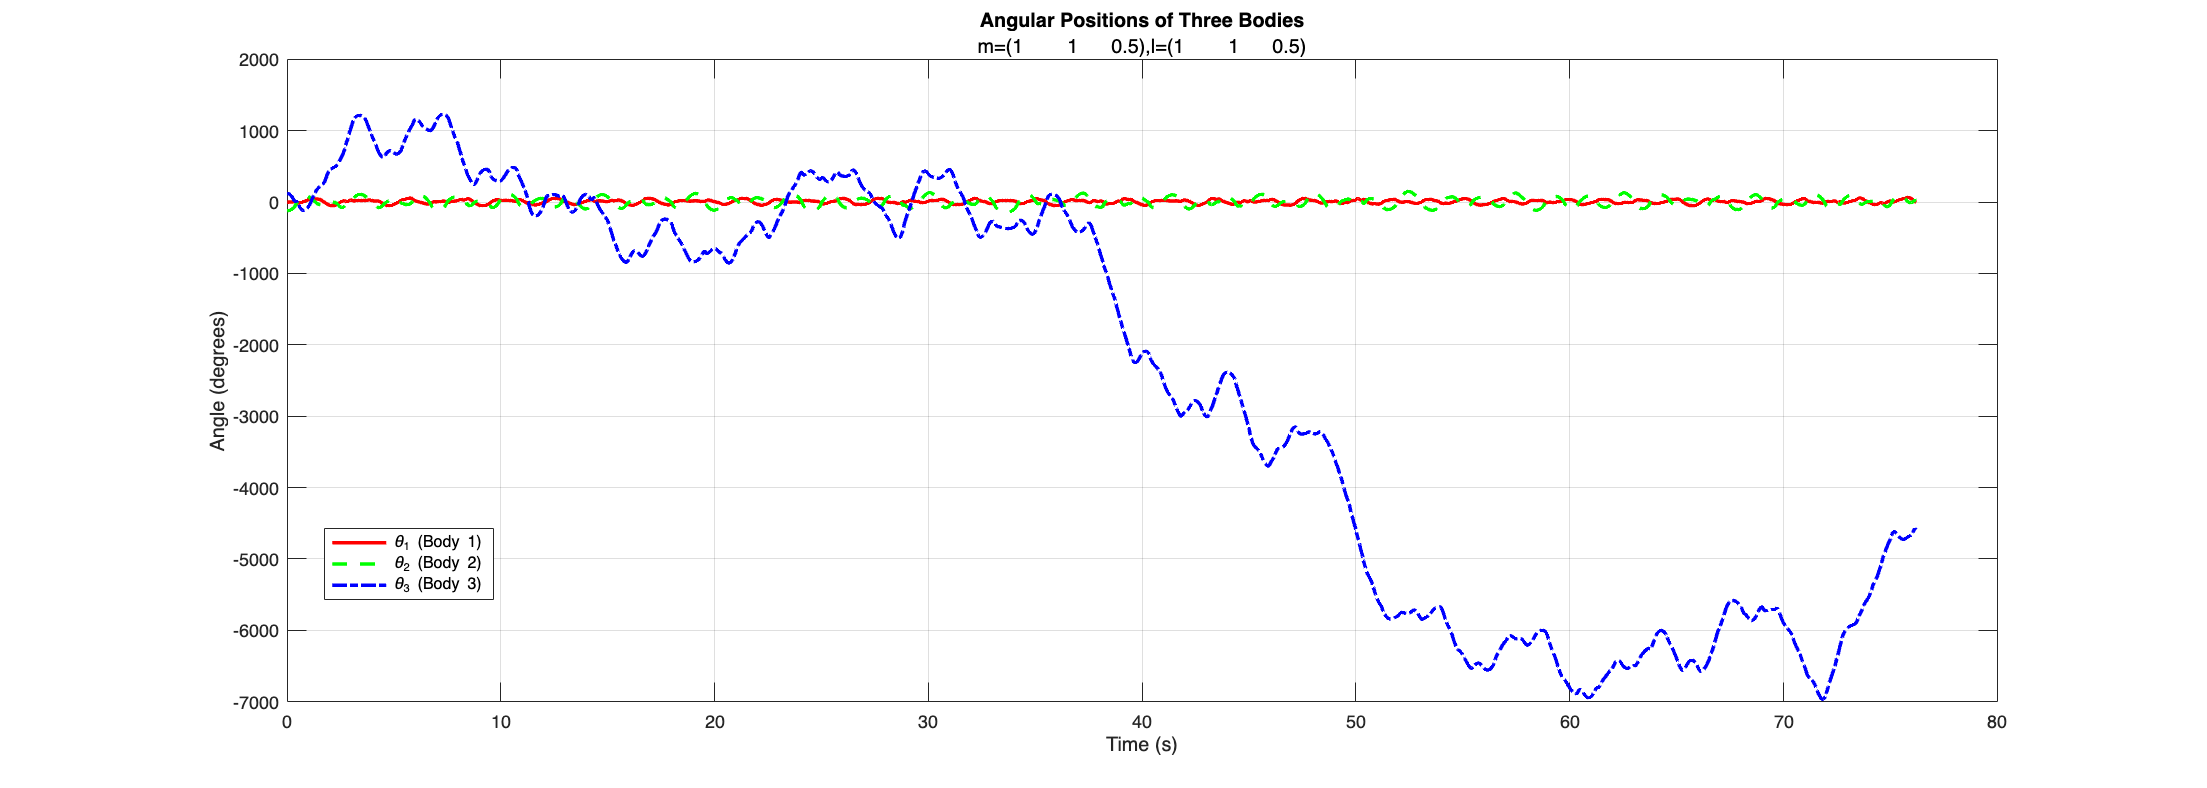

figure('Position', [100, 100, 1400, 500]);
plot(t_sol, theta1_sol * 180 / pi, 'r-', 'LineWidth', 2);
hold on;
plot(t_sol, theta2_sol * 180 / pi, 'g--', 'LineWidth', 2);
plot(t_sol, theta3_sol * 180 / pi, 'b-.', 'LineWidth', 2);
hold off;
xlabel('Time (s)');
ylabel('Angle (degrees)');
title('Angular Positions of Three Bodies');

msubtitle=num2str([m1_val,m2_val,m3_val],2);
lsubtitle=num2str([l1_val,l2_val,l3_val],2);
subtitle(strcat("m=(",msubtitle,"),l=(",lsubtitle,")"))

legend('\theta_1 (Body 1)', '\theta_2 (Body 2)', '\theta_3 (Body 3)', 'Location', 'best');
grid on;

## Plot the system energy over time

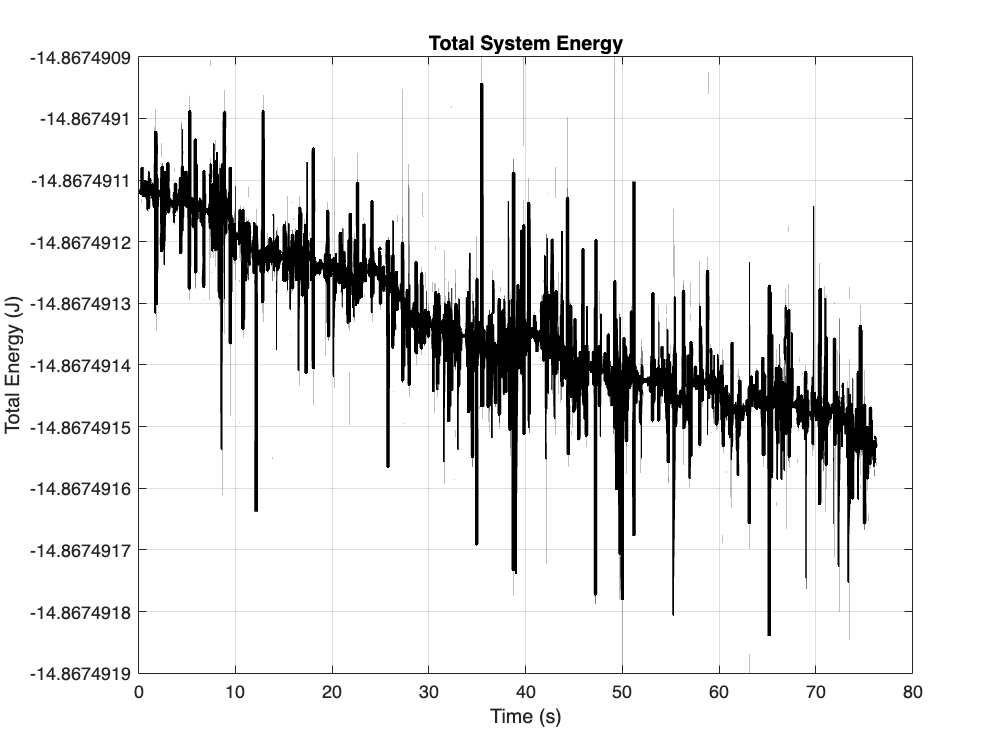

figure
plot(t_sol, energy, 'k-', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Total Energy (J)');
title('Total System Energy');
grid on;

## Animate the motion

tanimimation=tic;

Set the animation frame rate.

frame_rate = 30;

Set the time interval between frames.

dt_desired = 1 / frame_rate;

Create a time grid.

### Try this: Set the maximum animation time.

Animation is time-consuming. Set the maximum animation time in seconds as desired, independent of the maximum simulation time.

maxanimationtime_default=5;
maxanimationtime=61;
maxanimationtime=min([maxanimationtime,t_final]);
t_anim = 0:dt_desired:min([t_final,maxanimationtime]);

Interpolate the angles over time from the simulation to the animation time grid.

theta1_anim = interp1(t_sol, theta1_sol, t_anim);
theta2_anim = interp1(t_sol, theta2_sol, t_anim);
theta3_anim = interp1(t_sol, theta3_sol, t_anim);

Create an animation figure.

fig_anim = figure('Position', [100, 100, 600, 600]);
axis equal;
grid on;
hold on;

Set limits for the figure.

max_extent = l1_val + l2_val + 0.5;
xlim([-max_extent, max_extent]);
ylim([-max_extent, max_extent]);
xlabel('X (m)');
ylabel('Y (m)');
if strcmp(visualization_mode, 'special')
    title('Planet symbols');
else
    title('Triple Triangles');
end
msubtitle=num2str([m1_val,m2_val,m3_val],2);
lsubtitle=num2str([l1_val,l2_val,l3_val],2);
subtitle(strcat("m=(",msubtitle,"),l=(",lsubtitle,")"))

Initialize by plotting the objects at the origin.

pivot_plot = plot(0, 0, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');

Plot special or triangle shapes per user preference.

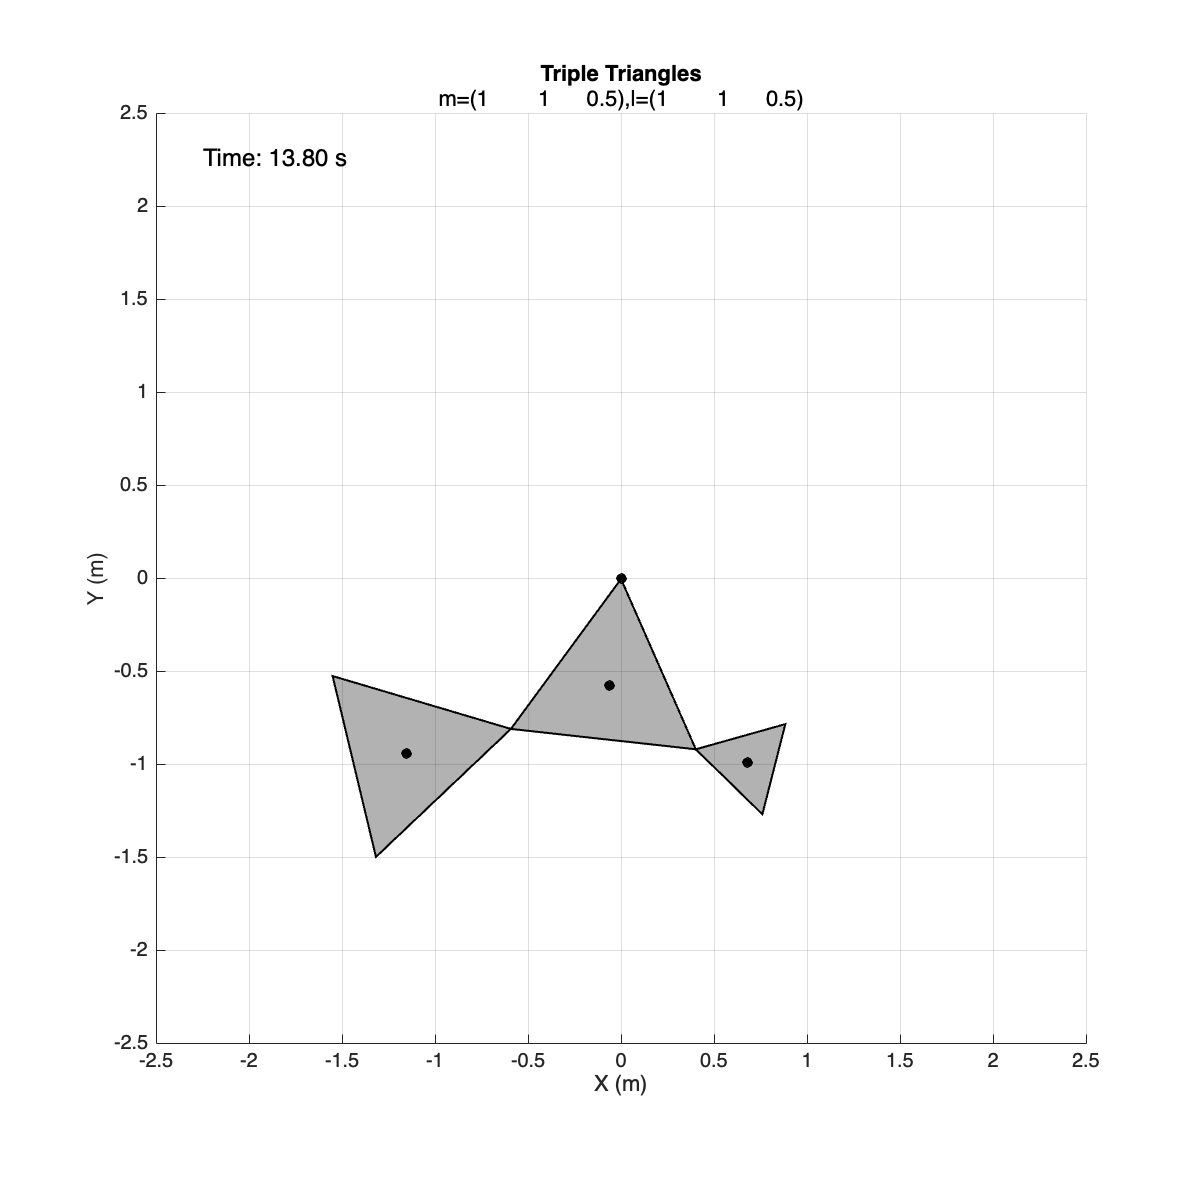

if strcmp(visualization_mode, 'special')
    body1_hoop = plot(0, 0, 'k-', 'LineWidth', 5);
    body2_cross_v = plot(0, 0, 'k-', 'LineWidth', 5);
    body2_cross_h = plot(0, 0, 'k-', 'LineWidth', 5);
    body3_arrow_shaft = plot(0, 0, 'k-', 'LineWidth', 5);
    body3_arrow_left = plot(0, 0, 'k-', 'LineWidth', 5);
    body3_arrow_right = plot(0, 0, 'k-', 'LineWidth', 5);
    cm1_plot = plot(0, 0, 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
    cm2_plot = plot(0, 0, 'go', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
    cm3_plot = plot(0, 0, 'bo', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
else
    tri1_plot = fill(0, 0, 'k', 'FaceAlpha', 0.3, 'EdgeColor', 'k', 'LineWidth', 1);
    tri2_plot = fill(0, 0, 'k', 'FaceAlpha', 0.3, 'EdgeColor', 'k', 'LineWidth', 1);
    tri3_plot = fill(0, 0, 'k', 'FaceAlpha', 0.3, 'EdgeColor', 'k', 'LineWidth', 1);
    cm1_plot = plot(0, 0, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
    cm2_plot = plot(0, 0, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
    cm3_plot = plot(0, 0, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
end

time_text = text(-max_extent*0.9, max_extent*0.9, '', 'FontSize', 12);


fprintf('Animating...\n');

Animating...


Loop over the animation time grid.

for i = 1:length(t_anim)
    th1 = theta1_anim(i);
    th2 = theta2_anim(i);
    th3 = theta3_anim(i);

Calculate vertices and centers of mass for all three bodies.

    v11 = [0; 0];
    v12 = [l1_val * sin(th1 - pi/6); -l1_val * cos(th1 - pi/6)];
    v13 = [l1_val * sin(th1 + pi/6); -l1_val * cos(th1 + pi/6)];
    cm1 = (v11 + v12 + v13) / 3;
    
    v21 = v12;
    v22 = v21 + [l2_val * sin(th2 - pi/6); -l2_val * cos(th2 - pi/6)];
    v23 = v21 + [l2_val * sin(th2 + pi/6); -l2_val * cos(th2 + pi/6)];
    cm2 = (v21 + v22 + v23) / 3;
    
    v31 = v13;
    v32 = v31 + [l3_val * sin(th3 - pi/6); -l3_val * cos(th3 - pi/6)];
    v33 = v31 + [l3_val * sin(th3 + pi/6); -l3_val * cos(th3 + pi/6)];
    cm3 = (v31 + v32 + v33) / 3;

Move objects to locations at the current animation time.    

    if strcmp(visualization_mode, 'special')

BODY 1: Circular hoop through vertices v11, v12, v13

        [hoop_center, hoop_radius] = circumcircle(v11, v12, v13);
        theta_circle = linspace(0, 2*pi, 100);
        hoop_x = hoop_center(1) + hoop_radius * cos(theta_circle);
        hoop_y = hoop_center(2) + hoop_radius * sin(theta_circle);
        set(body1_hoop, 'XData', hoop_x, 'YData', hoop_y);

BODY 2: Cross shape (vertical bar + horizontal bar)

        [cross_v_x, cross_v_y, cross_h_x, cross_h_y] = create_cross(v21, v22, v23, cm2, th2);
        set(body2_cross_v, 'XData', cross_v_x, 'YData', cross_v_y);
        set(body2_cross_h, 'XData', cross_h_x, 'YData', cross_h_y);

BODY 3: Arrow shape pointing down in equilibrium

        [arrow_shaft_x, arrow_shaft_y, arrow_left_x, arrow_left_y, ...
         arrow_right_x, arrow_right_y] = create_arrow(v31, v32, v33, th3, l3_val);
        set(body3_arrow_shaft, 'XData', arrow_shaft_x, 'YData', arrow_shaft_y);
        set(body3_arrow_left, 'XData', arrow_left_x, 'YData', arrow_left_y);
        set(body3_arrow_right, 'XData', arrow_right_x, 'YData', arrow_right_y);
        
    else

Standard triangle visualization

        set(tri1_plot, 'XData', [v11(1), v12(1), v13(1)], 'YData', [v11(2), v12(2), v13(2)]);
        set(tri2_plot, 'XData', [v21(1), v22(1), v23(1)], 'YData', [v21(2), v22(2), v23(2)]);
        set(tri3_plot, 'XData', [v31(1), v32(1), v33(1)], 'YData', [v31(2), v32(2), v33(2)]);
    end

Update locations of center of mass markers.

    set(cm1_plot, 'XData', cm1(1), 'YData', cm1(2));
    set(cm2_plot, 'XData', cm2(1), 'YData', cm2(2));
    set(cm3_plot, 'XData', cm3(1), 'YData', cm3(2));
    set(time_text, 'String', sprintf('Time: %.2f s', t_anim(i)));

Draw the figure and pause.

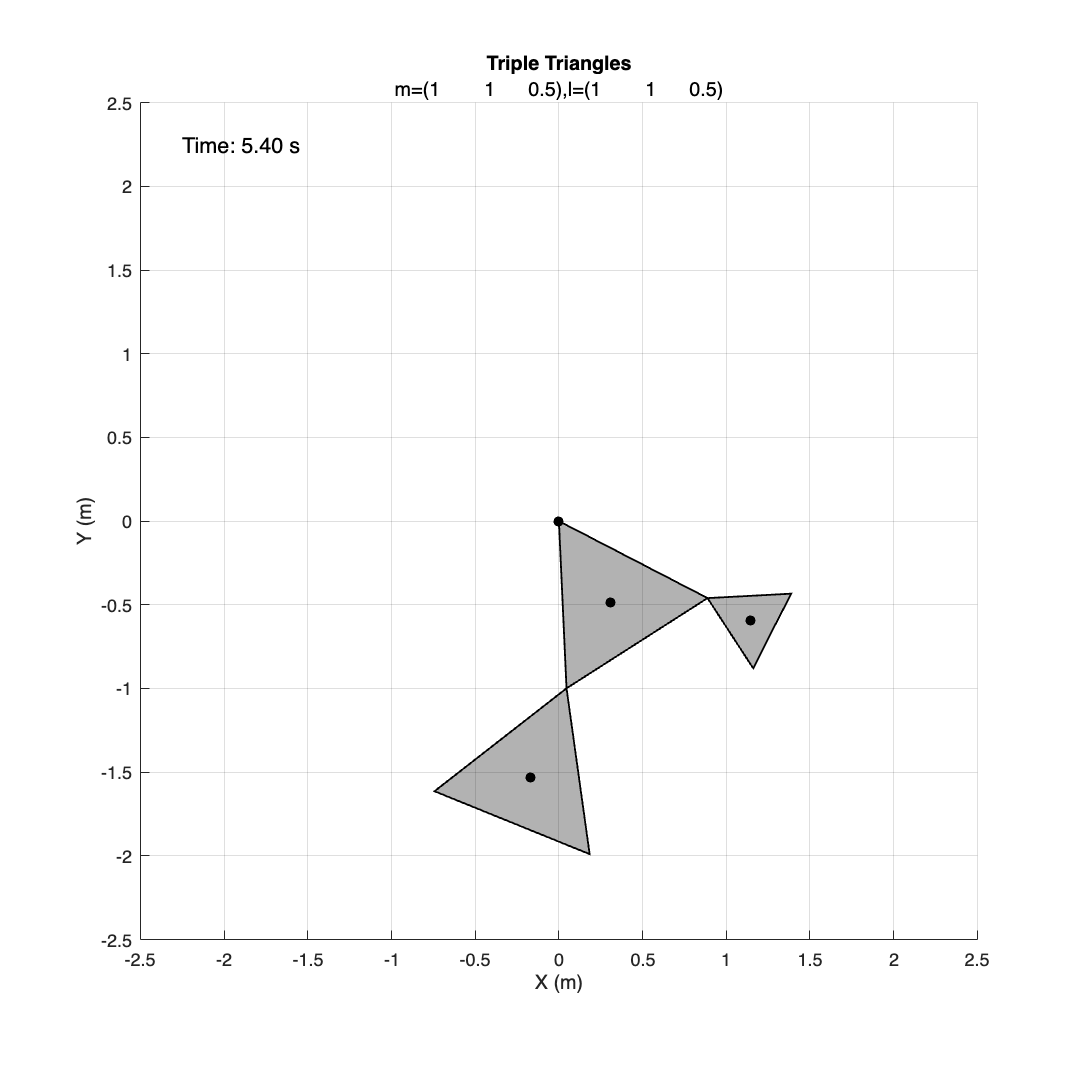

    drawnow;
    if i < length(t_anim)
        pause(dt_desired);
    end
end

toc(tanimimation);

## Normal mode analysis 

tic

Linearize about theta=[0 0 0].

q  = [theta1; theta2; theta3];
dq = [dtheta1; dtheta2; dtheta3];

Mass (quadratic in velocities) and stiffness (Hessian of V).

M_lin_sym = jacobian(jacobian(T, dq), dq);
M_lin_sym = subs(M_lin_sym, [theta1, theta2, theta3], [0, 0, 0]);
M_lin_sym = simplify(M_lin_sym);

K_lin_sym = hessian(V, q);
K_lin_sym = subs(K_lin_sym, [theta1, theta2, theta3], [0, 0, 0]);
K_lin_sym = simplify(K_lin_sym);

Substitute numeric parameters into mass and stiffness matrices.

M_lin = double(subs(M_lin_sym, [l1, l2, l3, m1, m2, m3, g], ...
                               [l1_val, l2_val, l3_val, m1_val, m2_val, m3_val, g_val]));
K_lin = double(subs(K_lin_sym, [l1, l2, l3, m1, m2, m3, g], ...
                               [l1_val, l2_val, l3_val, m1_val, m2_val, m3_val, g_val]));

fprintf('\n=== SMALL-ANGLE MASS/ STIFFNESS MATRICES ===\n');
disp('M_lin ='); disp(M_lin);
disp('K_lin ='); disp(K_lin);

Solve the generalized eigenproblem:  K*phi = (omega^2) * M * phi

[Phi_raw, D_raw] = eig(K_lin, M_lin);
omega2 = real(diag(D_raw));
omega2(omega2 < 0) = 0;                  % guard tiny negatives
omega = sqrt(omega2);
[omega, idx] = sort(omega, 'ascend');
Phi_raw = Phi_raw(:, idx);

Mass-normalize, then scale so max|component| = 1 (for consistent display)

Phi = zeros(size(Phi_raw));
for i = 1:size(Phi_raw,2)
    v = real(Phi_raw(:,i));
    mnorm = sqrt(max(v.'*M_lin*v, 0));
    if mnorm > 0, v = v / mnorm; end
    vmax = max(abs(v));
    if vmax > 0, v = v / vmax; end
    Phi(:,i) = v;
end

Convert angular eigenfrequencies to Hz.

f_hz = omega / (2*pi);
fprintf('Natural frequencies (Hz): %0.6f, %0.6f, %0.6f\n', f_hz(1), f_hz(2), f_hz(3));

## Animate the normal modes

Initialize normal mode animations.

Set display amplitude (deg)

mode_amp_deg   = 5;                

Set amplitude of the normal mode.

A              = deg2rad(mode_amp_deg);
frame_rate     = 30;               
dt_mode        = 1 / frame_rate;   
axis_pad       = 0.5;
nm_max_extent  = l1_val + l2_val + axis_pad;

Loop over normal modes.

for r = 1:3
    if omega(r) <= 0
        fprintf('Mode %d has zero/imag frequency; skipping.\n', r);
        continue;
    end

Set number of periods for normal mode animation

    Tr       = 2*pi/omega(r);
    t_end    = 5*Tr;                        

Create animation time grid.

    t_mode   = 0:dt_mode:t_end;             
    Nf       = numel(t_mode);

Mode motion: q(t) = A * cos(omega*t) * phi

    phi      = Phi(:,r).';
    th1_mode = A * phi(1) * cos(omega(r)*t_mode);
    th2_mode = A * phi(2) * cos(omega(r)*t_mode);
    th3_mode = A * phi(3) * cos(omega(r)*t_mode);

Diagnostics.

    dth = max(abs(diff([th1_mode; th2_mode; th3_mode],1,2)),[],2);
    fprintf('\n=== Creating Mode %d Animation ===\n', r);
    fprintf('Mode %d: Tr=%0.3f s, frames=%d, dt=%0.4f s, f=%0.4f Hz\n', r, Tr, Nf, dt_mode, f_hz(r));
    fprintf('        phi^T = [%g  %g  %g]\n', phi(1), phi(2), phi(3));
    fprintf('        peak |theta| = [%0.5f  %0.5f  %0.5f] rad (target max = %0.5f rad)\n', ...
            max(abs(th1_mode)), max(abs(th2_mode)), max(abs(th3_mode)), A);
    fprintf('        max |Δθ| per step = [%0.5f  %0.5f  %0.5f] rad\n', dth(1), dth(2), dth(3));

Initialize figures.

    nm_fig(r) = figure('Position', [100+50*(r-1), 100+50*(r-1), 600, 600]);
    axis equal;
    grid on;
    hold on;

Set figure limits.

    xlim([-nm_max_extent, nm_max_extent]);
    ylim([-nm_max_extent, nm_max_extent]);
    xlabel('X (m)');
    ylabel('Y (m)');

Create figure title.

    if strcmp(visualization_mode, 'special')
        title(sprintf('Normal Mode %d (f=%.3f Hz) — special shapes', r, f_hz(r)));
    else
        title(sprintf('Normal Mode %d (f=%.3f Hz) — triangles', r, f_hz(r)));
    end

    msubtitle=num2str([m1_val,m2_val,m3_val],2);
    lsubtitle=num2str([l1_val,l2_val,l3_val],2);
    subtitle(strcat("m=(",msubtitle,"),l=(",lsubtitle,")"))

Initialize marker for pivot point.

    nm_pivot_plot = plot(0, 0, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');

Draw objects per users visualization choice.

    if strcmp(visualization_mode, 'special')

Special shapes mode

        nm_body1_hoop      = plot(0, 0, 'k-', 'LineWidth', 5);
        nm_body2_cross_v   = plot(0, 0, 'k-', 'LineWidth', 5);
        nm_body2_cross_h   = plot(0, 0, 'k-', 'LineWidth', 5);
        nm_body3_arrow_shaft = plot(0, 0, 'k-', 'LineWidth', 5);
        nm_body3_arrow_left  = plot(0, 0, 'k-', 'LineWidth', 5);
        nm_body3_arrow_right = plot(0, 0, 'k-', 'LineWidth', 5);
        nm_cm1_plot = plot(0, 0, 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
        nm_cm2_plot = plot(0, 0, 'go', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
        nm_cm3_plot = plot(0, 0, 'bo', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
    else

Triangle shapes mode

        nm_tri1_plot = fill(0, 0, 'k', 'FaceAlpha', 0.3, 'EdgeColor', 'k', 'LineWidth', 1);
        nm_tri2_plot = fill(0, 0, 'k', 'FaceAlpha', 0.3, 'EdgeColor', 'k', 'LineWidth', 1);
        nm_tri3_plot = fill(0, 0, 'k', 'FaceAlpha', 0.3, 'EdgeColor', 'k', 'LineWidth', 1);
        nm_cm1_plot  = plot(0, 0, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
        nm_cm2_plot  = plot(0, 0, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
        nm_cm3_plot  = plot(0, 0, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
    end

    nm_time_text = text(-nm_max_extent*0.9, nm_max_extent*0.9, '', 'FontSize', 12);

Loop over frames.

    fprintf('Animating Mode %d...\n', r);
    for k = 1:Nf
        if strcmp(visualization_mode, 'special')
            title(sprintf('Normal Mode %d (f=%.3f Hz) — special shapes', r, f_hz(r)));
        else
            title(sprintf('Normal Mode %d (f=%.3f Hz) — triangles', r, f_hz(r)));
        end
        nm_th1 = th1_mode(k);
        nm_th2 = th2_mode(k);
        nm_th3 = th3_mode(k);

        nm_v11 = [0; 0];
        nm_v12 = [l1_val * sin(nm_th1 - pi/6); -l1_val * cos(nm_th1 - pi/6)];
        nm_v13 = [l1_val * sin(nm_th1 + pi/6); -l1_val * cos(nm_th1 + pi/6)];
        nm_cm1 = (nm_v11 + nm_v12 + nm_v13) / 3;

        nm_v21 = nm_v12;
        nm_v22 = nm_v21 + [l2_val * sin(nm_th2 - pi/6); -l2_val * cos(nm_th2 - pi/6)];
        nm_v23 = nm_v21 + [l2_val * sin(nm_th2 + pi/6); -l2_val * cos(nm_th2 + pi/6)];
        nm_cm2 = (nm_v21 + nm_v22 + nm_v23) / 3;

        nm_v31 = nm_v13;
        nm_v32 = nm_v31 + [l3_val * sin(nm_th3 - pi/6); -l3_val * cos(nm_th3 - pi/6)];
        nm_v33 = nm_v31 + [l3_val * sin(nm_th3 + pi/6); -l3_val * cos(nm_th3 + pi/6)];
        nm_cm3 = (nm_v31 + nm_v32 + nm_v33) / 3;

        if strcmp(visualization_mode, 'special')

Body 1: Circular hoop through nm_v11, nm_v12, nm_v13

            [nm_hoop_center, nm_hoop_radius] = circumcircle(nm_v11, nm_v12, nm_v13);
            nm_theta_circle = linspace(0, 2*pi, 100);
            nm_hoop_x = nm_hoop_center(1) + nm_hoop_radius * cos(nm_theta_circle);
            nm_hoop_y = nm_hoop_center(2) + nm_hoop_radius * sin(nm_theta_circle);
            set(nm_body1_hoop, 'XData', nm_hoop_x, 'YData', nm_hoop_y);

Body 2: Cross

            [nm_cross_v_x, nm_cross_v_y, nm_cross_h_x, nm_cross_h_y] = ...
                create_cross(nm_v21, nm_v22, nm_v23, nm_cm2, nm_th2);
            set(nm_body2_cross_v, 'XData', nm_cross_v_x, 'YData', nm_cross_v_y);
            set(nm_body2_cross_h, 'XData', nm_cross_h_x, 'YData', nm_cross_h_y);

Body 3: Arrow

            [nm_arrow_shaft_x, nm_arrow_shaft_y, nm_arrow_left_x, nm_arrow_left_y, ...
             nm_arrow_right_x, nm_arrow_right_y] = create_arrow(nm_v31, nm_v32, nm_v33, nm_th3, l3_val);
            set(nm_body3_arrow_shaft, 'XData', nm_arrow_shaft_x, 'YData', nm_arrow_shaft_y);
            set(nm_body3_arrow_left,  'XData', nm_arrow_left_x,  'YData', nm_arrow_left_y);
            set(nm_body3_arrow_right, 'XData', nm_arrow_right_x, 'YData', nm_arrow_right_y);
        else

 Triangles

            set(nm_tri1_plot, 'XData', [nm_v11(1), nm_v12(1), nm_v13(1)], ...
                             'YData', [nm_v11(2), nm_v12(2), nm_v13(2)]);
            set(nm_tri2_plot, 'XData', [nm_v21(1), nm_v22(1), nm_v23(1)], ...
                             'YData', [nm_v21(2), nm_v22(2), nm_v23(2)]);
            set(nm_tri3_plot, 'XData', [nm_v31(1), nm_v32(1), nm_v33(1)], ...
                             'YData', [nm_v31(2), nm_v32(2), nm_v33(2)]);
        end

Centers of mass.

        set(nm_cm1_plot, 'XData', nm_cm1(1), 'YData', nm_cm1(2));
        set(nm_cm2_plot, 'XData', nm_cm2(1), 'YData', nm_cm2(2));
        set(nm_cm3_plot, 'XData', nm_cm3(1), 'YData', nm_cm3(2));

        set(nm_time_text, 'String', sprintf('Mode %d  t = %.3f s', r, t_mode(k)));

Use the same draw cadence as simulation animation.

        drawnow;
        if k < Nf
            pause(dt_mode);
        end
    end
    fprintf('Mode %d animation complete.\n', r);
end
toc
fprintf('\n=== SIMULATION COMPLETE ===\n');

## Run chaos diagnostics code

t1=tic;
run('TriplePendulumChaosDiagnostics.mlx');
toc(t1)

## Wrap up

toc(t0)
license("inuse")
version

## Challenges

### Damping and forcing

The model in this script conserves . Any motion is constrained to a constant-energy manifold in phase space. Energy-conserving chaos preserves phase space volume (Liouville's theorem), and trajectories densely fill the constant energy manifold depending on the degree of chaos. Dissipation contracts phase space volume, and chaotic trajectories are attracted to lower-dimensional sets called strange attractors—not the entire constant energy surface. 

Explore generalized equations of motions of the form


$$I_i\ddot\theta_i+b_i\dot\theta_i+f_i(\theta_1,\theta_2,\theta_3)=f_i$$


where $b_i$ is an inverse damping time and $f_i(t)$ i a forcing function. When forces are given as Cartesian forces on the mass, compute generalized forces by projecting forces onto generalized coordinate directions:

$f_j= \sum_{i=1}^N[F_{xi}(t){\partial x_i\over \partial\theta_j}+F_{yi}(t){\partial y_i\over \partial\theta_j}+F_{xi}(t){\partial z_i\over \partial\theta_j}$. 

When forces are given as torques directly on the generalized coordinates, include them as the generalized forces  on the right hand side of the Euler–Lagrange equations without further transformation.

### Lyapunov exponent direct calculation

The Lyapunov exponent describes the approximate exponential growth in the separation in phase space of two trajectories with some initial separation. Modify the code to perturb the initial conditions along each of the six axes in phase space (three angles and three initial angular velocities). Use unwrapped angles to avoid discontinuities. Characterize the separation of the perturbed trajectories from the unperturbed ones over time.

## Acknowledgments

The code in this script was created with the assistance of of [open.ai](http://open.ai) ChatGPT 5o and [perplexity.ai](http://perplexity.ai) (GPT 4o and Claude Sonnet 3.7) 

## References

[1] [Double Pendulum Ring ](https://www.reddit.com/r/oddlysatisfying/comments/ps9are/double_pendulum_ring_and_bar/?utm_source=share&utm_medium=web3x&utm_name=web3xcss&utm_term=1&utm_content=share_button)(YouTube)

[2] [Double Pendulum Chaotic Gymnastics](https://www.youtube.com/watch?v=EjNAyOFcwoc) (YouTube)

[3] Duncan Carlsmith (2025). Normal Modes of a System of Masses ([https://www.mathworks.com/matlabcentral/fileexchange/182377-normal-modes-of-a-system-of-masses](https://www.mathworks.com/matlabcentral/fileexchange/182377-normal-modes-of-a-system-of-masses)), MATLAB Central File Exchange. Retrieved October 31, 2025.

[4] [Animation and Solution of Double Pendulum Motion](https://www.mathworks.com/help/symbolic/animation-and-solution-of-double-pendulum.html?ref=engineered-mind.com) (MathWorks example using Newton's Laws)

[5] Mansour Torabi (2025). Matlab Euler-Lagrange Library  [https://github.com/Mansourt/Matlab_Euler-Lagrange_Library_for_Deriving_Equations_of_Dynamic_Systems](https://github.com/Mansourt/Matlab_Euler-Lagrange_Library_for_Deriving_Equations_of_Dynamic_Systems) , GitHub. Retrieved October 28, 2025.

[6] Gottwald, Georg A., and Ian Melbourne. "A new test for chaos in deterministic systems." *Proceedings of the Royal Society of London. Series A: Mathematical, Physical and Engineering Sciences* 460.2042 (2004): 603-611. [https://doi.org/10.1098/rspa.2003.1183;](https://doi.org/10.1098/rspa.2003.1183;) Gottwald, Georg A., and Ian Melbourne. "The 0-1 test for chaos: A review." *Chaos detection and predictability* (2016): 221-247. [https://doi.org/10.1007/978-3-662-48410-4_7](https://doi.org/10.1007/978-3-662-48410-4_7) .

[7] Grassberger, Peter, and Itamar Procaccia. "Characterization of strange attractors." *Physical review letters* 50.5 (1983): 346. [https://doi.org/10.1103/PhysRevLett.50.346](https://doi.org/10.1103/PhysRevLett.50.346) 

[8] Wolf, Alan, et al. "Determining Lyapunov exponents from a time series." *Physica D: nonlinear phenomena* 16.3 (1985): 285-317. [https://doi.org/10.1016/0167-2789(85)90011-9](https://doi.org/10.1016/0167-2789(85)90011-9)

[9] Jiménez-López, Javier, and Víctor J. García-Garrido. "Chaos and regularity in the double pendulum with lagrangian descriptors." *International Journal of Bifurcation and Chaos* 34.16 (2024): 2450201.

## Helper Functions

### triple_pendulum_ode

function dydt = triple_pendulum_ode(~, y, M_func, F_func)
    %
    % ODE function for triple pendulum
    %
    
    theta1 = y(1);
    theta2 = y(2);
    theta3 = y(3);
    dtheta1 = y(4);
    dtheta2 = y(5);
    dtheta3 = y(6);
    
    M = M_func(theta1, theta2, theta3, dtheta1, dtheta2, dtheta3);
    F = F_func(theta1, theta2, theta3, dtheta1, dtheta2, dtheta3);
    
    ddq = M \ F;
    
    dydt = zeros(6, 1);
    dydt(1) = dtheta1;
    dydt(2) = dtheta2;
    dydt(3) = dtheta3;
    dydt(4) = ddq(1);
    dydt(5) = ddq(2);
    dydt(6) = ddq(3);
end

### circumcircle

function [center, radius] = circumcircle(p1, p2, p3)
    %
    % Calculate circumcircle passing through three points
    %
    % Uses the perpendicular bisector method
    %
    
    ax = p1(1); ay = p1(2);
    bx = p2(1); by = p2(2);
    cx = p3(1); cy = p3(2);
    
    D = 2 * (ax * (by - cy) + bx * (cy - ay) + cx * (ay - by));
    
    ux = ((ax^2 + ay^2) * (by - cy) + (bx^2 + by^2) * (cy - ay) + (cx^2 + cy^2) * (ay - by)) / D;
    uy = ((ax^2 + ay^2) * (cx - bx) + (bx^2 + by^2) * (ax - cx) + (cx^2 + cy^2) * (bx - ax)) / D;
    
    center = [ux; uy];
    radius = sqrt((ax - ux)^2 + (ay - uy)^2);
end

### create_cross

function [v_x, v_y, h_x, h_y] = create_cross(v1, v2, v3, cm, angle)
    %
    % Create cross shape for Body 2
    % In equilibrium (angle=0): vertical bar from pivot to opposite vertex
    %                           horizontal bar through center of mass
    %
    
    %
    % For an equilateral triangle, find the "base" vertices and "top" vertex
    % The pivot is v1, we want vertical bar from v1 to the midpoint of opposite side
    %
    midpoint_base = (v2 + v3) / 2;
    
    %
    % Vertical bar: from pivot (v1) to opposite midpoint
    %
    v_x = [v1(1), midpoint_base(1)];
    v_y = [v1(2), midpoint_base(2)];
    
    %
    % Horizontal bar: through center of mass, perpendicular to vertical
    % Find direction perpendicular to vertical bar
    %
    vert_dir = midpoint_base - v1;
    vert_dir = vert_dir / norm(vert_dir);
    perp_dir = [-vert_dir(2); vert_dir(1)];
    
    %
    % Horizontal bar extends to touch the two side vertices
    % Length is the distance from CM to either v2 or v3
    %
    half_length = norm(v2 - cm);
    
    h_pt1 = cm - half_length * perp_dir;
    h_pt2 = cm + half_length * perp_dir;
    
    h_x = [h_pt1(1), h_pt2(1)];
    h_y = [h_pt1(2), h_pt2(2)];
end

### create_arrowinpointing

function [shaft_x, shaft_y, left_x, left_y, right_x, right_y] = create_arrowinpointing(v1, v2, v3, angle, Length)
    %
    % Create arrow shape for Body 3
    % Arrow points downward in equilibrium (angle=0)    
    %
    % Arrow shaft: from pivot (v1) to opposite midpoint
    %
    midpoint_base = (v2 + v3) / 2;
    shaft_x = [v1(1), midpoint_base(1)];
    shaft_y = [v1(2), midpoint_base(2)];    
    %
    % Arrow head: two lines at 45 degrees from the shaft direction
    % The arrowhead starts at the pivot (v1)
    %
    shaft_dir = midpoint_base - v1;
    shaft_length = norm(shaft_dir);
    shaft_dir = shaft_dir / shaft_length;    
    %
    % Arrowhead length is about 1/3 of the total length
    %
    head_length = shaft_length / 3;    
    %
    % Left arrow line: 45 degrees counterclockwise from shaft
    %
    angle_left = atan2(shaft_dir(2), shaft_dir(1)) - pi/4;
    left_end = v1 + head_length * [cos(angle_left); sin(angle_left)];
    left_x = [v1(1), left_end(1)];
    left_y = [v1(2), left_end(2)];    
    %
    % Right arrow line: 45 degrees clockwise from shaft
    %
    angle_right = atan2(shaft_dir(2), shaft_dir(1)) + pi/4;
    right_end = v1 + head_length * [cos(angle_right); sin(angle_right)];
    right_x = [v1(1), right_end(1)];
    right_y = [v1(2), right_end(2)];
end

### create_arrow

function [shaft_x, shaft_y, left_x, left_y, right_x, right_y] = create_arrow(v1, v2, v3, angle, Length)
    %
    % Create arrow shape for Body 3
    % Arrow points UPWARD in equilibrium (angle=0) - REVERSED
    %
    % Arrow shaft: from opposite midpoint to pivot (REVERSED)
    %
    midpoint_base = (v2 + v3) / 2;
    shaft_x = [midpoint_base(1), v1(1)];  % REVERSED ORDER
    shaft_y = [midpoint_base(2), v1(2)];  % REVERSED ORDER    
    %
    % Arrow head: two lines at 45 degrees from the shaft direction
    % The arrowhead is now at the midpoint (REVERSED)
    %
    shaft_dir = v1 - midpoint_base;  % REVERSED DIRECTION
    shaft_length = norm(shaft_dir);
    shaft_dir = shaft_dir / shaft_length;    
    %
    % Arrowhead length is about 1/3 of the total length
    %
    head_length = shaft_length / 3;    
    %
    % Left arrow line: 45 degrees counterclockwise from shaft
    %
    angle_left = atan2(shaft_dir(2), shaft_dir(1)) - pi/4;
    left_end = midpoint_base + head_length * [cos(angle_left); sin(angle_left)];  % FROM midpoint_base
    left_x = [midpoint_base(1), left_end(1)];  % FROM midpoint_base
    left_y = [midpoint_base(2), left_end(2)];  % FROM midpoint_base    
    %
    % Right arrow line: 45 degrees clockwise from shaft
    %
    angle_right = atan2(shaft_dir(2), shaft_dir(1)) + pi/4;
    right_end = midpoint_base + head_length * [cos(angle_right); sin(angle_right)];  % FROM midpoint_base
    right_x = [midpoint_base(1), right_end(1)];  % FROM midpoint_base
    right_y = [midpoint_base(2), right_end(2)];  % FROM midpoint_base
end